# Risposte di Funzioni Di Trasferimento (FDT)

## Setup

close all;
clear all;
clc;

## Variabili simboliche

syms Yel(s)
syms yel(t)

## Esempio

tt = linspace(0, 10, 1000);

### Esercizio 2.11.1

#### FDT

G = tf([9 1], [2 3 2])

G =
 
      9 s + 1
  ---------------
  2 s^2 + 3 s + 2
 
Continuous-time transfer function.



#### Modello del sistema

[A,B,C,D] = tf2ss(G.Numerator{1}, G.Denominator{1})

A =    -1.5000   -1.0000
    1.0000         0


B =      1
     0


C =     4.5000    0.5000


D = 0

#### Autovalori

eig(A)

ans =   -0.7500 + 0.6614i
  -0.7500 - 0.6614i


#### Evoluzione libera

Trasformata

Yel(s) = simplify(free_evolution(A, C, ones(size(C))'));
pretty(Yel)

   20 s - 13
--------------
   2
4 s  + 6 s + 4



Evoluzione libera nel dominio del tempo

yel(t) = simplify(ilaplace(Yel));
pretty(vpa(yel, 4))

exp(-0.75 t) (cos(0.6614 t) - sin(0.6614 t) 2.117) 5.0



#### Grafico

Evoluzione libera

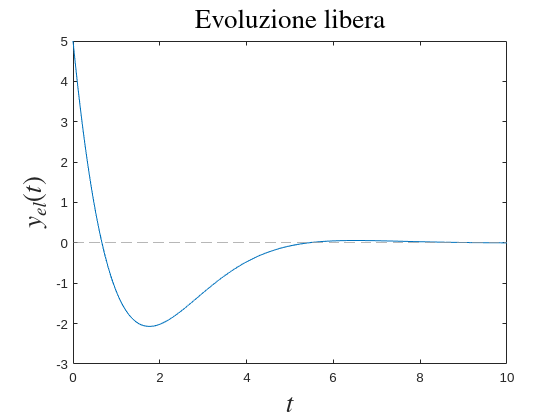

figure('Name','Evoluzione libera')
plot(tt, yel(tt))
xlim([tt(1) tt(end)])
xlabel('$$t$$', 'interpreter','latex', 'FontSize',20)
ylabel('$$y_{el}(t)$$', 'Interpreter','latex', 'FontSize',20)
yline(double(yel(tt(end))), '--', 'LineWidth',0.5, 'Color',[0.6 0.6 0.6])
title("Evoluzione libera", 'Interpreter','latex', 'FontSize',20)

Risposta al gradino

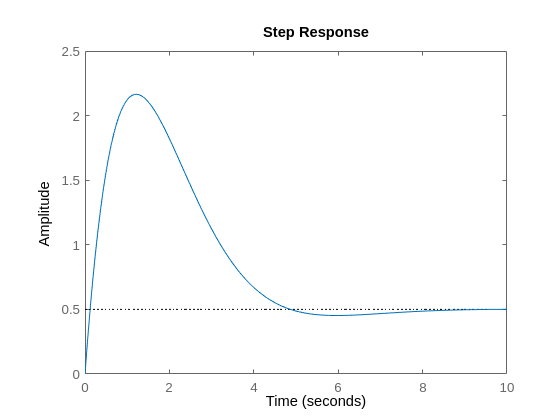

figure('Name','Risposta al gradin0')
step(G)

### Altri esempi

Funzione di trasferimento

G = tf(zpk([], [-1+1j, -1-1j -10], 1))

G =
 
             1
  ------------------------
  s^3 + 12 s^2 + 22 s + 20
 
Continuous-time transfer function.



[A,B,C,D] = tf2ss(G.Numerator{1}, G.Denominator{1})

A =    -12   -22   -20
     1     0     0
     0     1     0


B =      1
     0
     0


C =      0     0     1


D = 0

eig(A)

ans =  -10.0000 + 0.0000i
  -1.0000 + 1.0000i
  -1.0000 - 1.0000i


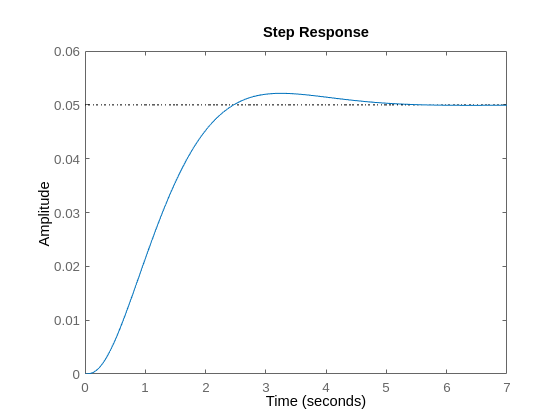

step(G)